%question_1

%import data
dataset = importdata('/Users/ethanvictormonkhouse/midterm2021.php')

dataset =      1     2     1
     1     2     3
     0     0     1
     0     0     2
     1     2     0
     1     3     0
     0     1     0
     1     2     3
     0     1     3
     1     2     3


[numberOfRows,numberOfColumns]=size(dataset);
fprintf("The dataset contains %d rows, and %d columns. \n", numberOfRows, numberOfColumns);

The dataset contains 1435 rows, and 3 columns. 


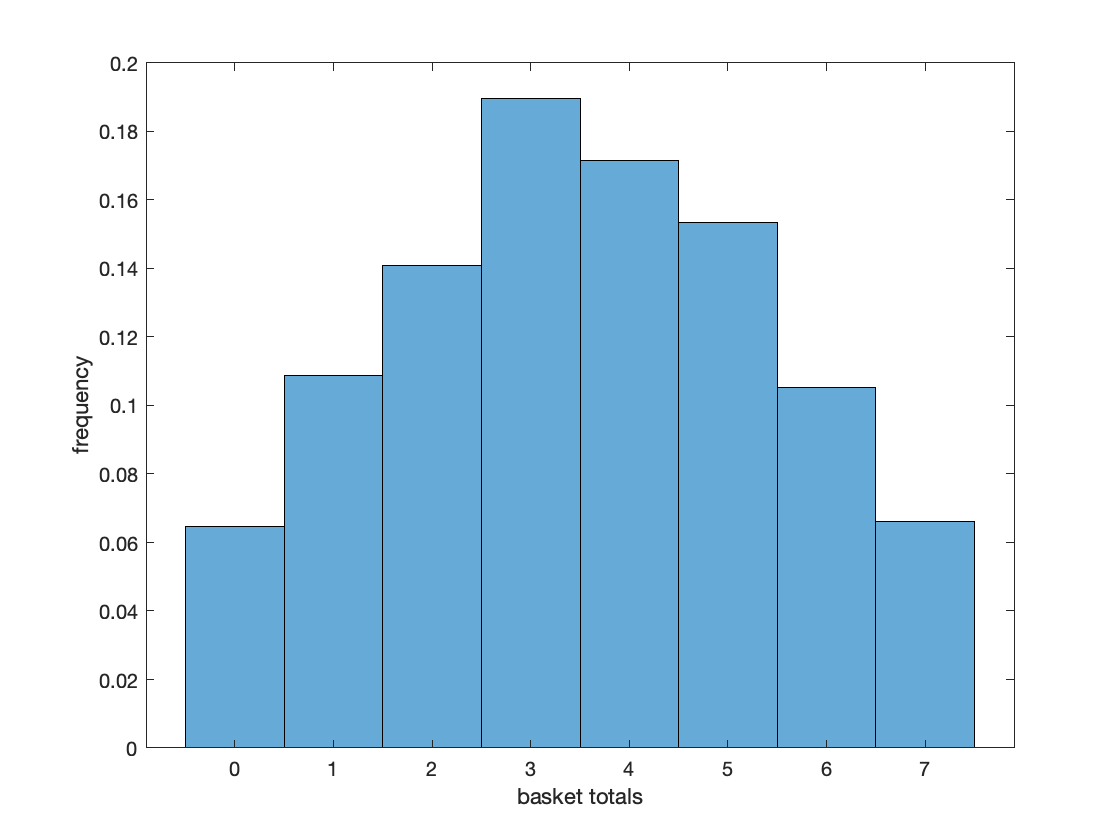


%part_a
a_rowSum = sum(dataset,2); %calculate sum of each basket
histogram(a_rowSum,2,'BinMethod','auto','Normalization', 'pdf'); %generate pmf

xlabel('basket totals')
ylabel('frequency')


%part_b
b_probability=sum(dataset(:,1)==1)/numberOfRows; %sum of observations/population
fprintf("P(Zi,1 = 1) is equal to %f \n", b_probability);

P(Zi,1 = 1) is equal to 0.510105 



%part_c
c_mean=(sum(dataset(:,1)==1)/numberOfRows); %population mean = sum/population
fprintf("The estimated population mean when P(Zi,1 = 1) is %f \n", c_mean); %print

The estimated population mean when P(Zi,1 = 1) is 0.510105 


c_var = var(dataset(:,1)==1)/numberOfRows; %population variance = var(x)*(1/population)
fprintf("The estimated population variance when P(Zi,1 = 1) is %f \n", c_var); %print

The estimated population variance when P(Zi,1 = 1) is 0.000174 


c_std = sqrt(c_var); %standard deviation = square root of the variance
fprintf("The estimated population standard deviation when P(Zi,1 = 1) is %f \n", c_std); %print

The estimated population standard deviation when P(Zi,1 = 1) is 0.013201 



c_clt_lowerBound = c_mean - 2*(c_std); %CLT Lower Bound
c_clt_upperBound = c_mean + 2*(c_std); %CLT Upper Bound
fprintf("CLT 95-Percent Confidence Interval is [%f, %f]. \n", c_clt_lowerBound,c_clt_upperBound); %print

CLT 95-Percent Confidence Interval is [0.483703, 0.536507]. 



c_chebyshev_lowerBound = c_mean - c_std/sqrt(0.05); %Chebyshev Lower Bound
c_chebyshev_upperBound = c_mean + c_std/sqrt(0.05); %Chebyshev Upper Bound
fprintf("Chebyshev 95-Percent Confidence Interval is [%f, %f]. \n", c_chebyshev_lowerBound,c_chebyshev_upperBound); %print

Chebyshev 95-Percent Confidence Interval is [0.451068, 0.569141]. 



%part_d
d_var = var(dataset(:,1)==1) %variance

d_var = 0.2501

z2 = 0

T = 4×4 table
      Z        pz2        pz1       SampleMean
    _____    _______    ________    __________

    {[0]}    0.25784           0           0  
    {[1]}    0.24111    0.062021     0.25723  
    {[2]}    0.25226      0.1993     0.79006  
    {[3]}    0.24878     0.24878           1  
